# **Computing Spacecraft Navigation**

Math describing the spacecraft's position in space upon orbit

## **Calculating the Orbit **

#### Declare and initialize variables

m = 40339620;      %kg
t1 = 142;                                     %s        %COMPUTED FROM ROCKET.MLX
h0e = 300000;                                %m
Re = 6.371*10.^6;                           %m
Rm = 1.73744 * 10.^6                        %m

Rm = 1737440

RP = 356.5 * 10.^6                          %m

RP = 356500000

RA = 406.7 * 10.^6                          %m

RA = 406700000

Me = 5.976*10.^24;                          %kg
G = 6.673*10.^11                            %Nm^2kg

G = 6.6730e+11

g = 9.82;                                   %m/s^2
gm = 1.625;                                 %m/s^2
Nse = 3                  %Number of steps to navigate to the transition

Nse = 3

dt = 60                   %Time required to accelerate 

dt = 60


h0m = 110*10.^3                             %height to land to the moon (Apollo 11)

h0m = 110000

dhl0 = 0.1*h0m;
Nsm = 3                  %Number of steps to navigate to the transition to the moon

Nsm = 3

#### Initial Step

r0e = h0e + Re;
r0m = h0m + Rm;
c2 = 1-((gm.*Rm.^2)./(g .* Re.^2))

c2 = 0.9877

c1 = -2*RP

c1 = -713000000

c0 = RP.^2;
re = roots([c2, c1, c0])

re = 	1.0e+08 *

    4.0098
    3.2090


rt = re(re < RP)

rt = 3.2090e+08

hte = rt - r0e                               %Total distance to navigate from the earth to transition

hte = 3.1423e+08

htm = RP - rt- r0m                               %Total distance to navigate from the transition to moon

htm = 3.3752e+07

dhe = hte ./ Nse      

dhe = 1.0474e+08

dhm = htm ./ Nsm

dhm = 1.1251e+07

**Navigation from the earth to the transition**

he = zeros(Nse+1, 1);                            %Distance from the earth
rpe = zeros(Nse+1, 1);
rae = zeros(Nse+1, 1);
vpe = zeros(Nse+1, 1);
vae = zeros(Nse+1, 1);
dve = zeros(Nse+1, 1);
ae = zeros(Nse+1, 1);
Fe = zeros(Nse+1, 1);
for ii = 1:Nse+1
    he(ii) = h0e + (ii-1) * dhe;
    rpe(ii) = he(ii) + Re;
    rae(ii) = rpe(ii) + dhe;
    vpe(ii) = sqrt(2.*g.*Re.^2.*(1./rpe(ii)-1./rae(ii))./(1-(rpe(ii)./rae(ii)).^2));
    vae(ii) = (vpe(ii).*rpe(ii))./rae(ii);
    if ii==1
        dve(ii) = vpe(ii);
    else
        dve(ii) = vpe(ii)-vae(ii-1);
    end
    ae(ii) = dve(ii) ./ dt;
    Fe(ii) = ae(ii) * m;
end
he'

ans = 	1.0e+08 *

    0.0030    1.0504    2.0979    3.1453


rpe'

ans = 	1.0e+08 *

    0.0667    1.1141    2.1616    3.2090


rae'

ans = 	1.0e+08 *

    1.1141    2.1616    3.2090    4.2564


vpe'

ans = 	1.0e+04 *

    1.0618    0.2173    0.1484    0.1190


vae'

ans = 	1.0e+03 *

    0.6358    1.1200    0.9999    0.8972


dve'

ans = 	1.0e+04 *

    1.0618    0.1537    0.0364    0.0190


ae'

ans =   176.9718   25.6187    6.0746    3.1698


Fe'

ans = 	1.0e+09 *

    7.1390    1.0334    0.2450    0.1279


sum(Fe)

ans = 8.5453e+09

#### **Navigation from the transition to the moon   **

hm = zeros(Nsm+1, 1);                            
rpm = zeros(Nsm+1, 1);
ram = zeros(Nsm+1, 1);
vpm = zeros(Nsm+1, 1);
vam = zeros(Nsm+1, 1);
dvm = zeros(Nsm+1, 1);
am = zeros(Nsm+1, 1);
Fm = zeros(Nsm+1, 1);
for ii = 1:Nsm+1
    hm(ii) = (htm + h0m) - (ii-1) * dhm;  
    rpm(ii) = Rm + hm(ii) - dhm;
    ram(ii) = hm(ii) + Rm;
    vpm(ii) = sqrt(2.*gm.*Rm.^2.*(1./rpm(ii)-1./ram(ii))./(1-(rpm(ii)./ram(ii)).^2));
    vam(ii) = (vpm(ii).*rpm(ii))./ram(ii);
    if ii==1
        dvm(ii) = vam(ii) - vae(end,1);
    else
        dvm(ii) = vam(ii)-vpm(ii);
    end
    am(ii) = dvm(ii) ./ dt;
    Fm(ii) = am(ii) * m;
end

hm

hm = 	1.0e+07 *

    3.3862
    2.2611
    1.1361
    0.0110


rpm'

ans = 	1.0e+07 *

    2.4349    1.3098    0.1847   -0.9403


ram'

ans = 	1.0e+07 *

    3.5599    2.4349    1.3098    0.1847


vpm'

ans = 	1.0e+03 *

    0.4892    0.6979    2.1573    0.5051


vam'

ans = 	1.0e+03 *

    0.3346    0.3754    0.3043   -2.5708


dvm'

ans = 	1.0e+03 *

   -0.5627   -0.3225   -1.8530   -3.0759


am'

ans =    -9.3781   -5.3744  -30.8840  -51.2643


Fm'

ans = 	1.0e+09 *

   -0.3783   -0.2168   -1.2458   -2.0680


sum(Fm)

ans = -3.9089e+09

**Descent **

tl0 = sqrt(2*dhl0 ./ gm)

tl0 = 116.3549


vl0 = 0

vl0 = 0

vl1 = vl0 + gm*tl0

vl1 = 189.0767


dhl1 = h0m - dhl0;

Fr = m*((gm*tl0).^2/(2*dhl1) + gm)

Fr = 72835425


tl1 = (gm*tl0)./(-gm+(Fr/m))

tl1 = 1.0472e+03


tlt = tl0 + tl1

tlt = 1.1635e+03


Np = 100;
hl = zeros(Np, 1);
tl = zeros(Np, 1);
vl = zeros(Np, 1);

for jj = 1:Np
    tl(jj, 1) = (jj-1) * (tlt ./ (Np - 1));
    if (tl(jj, 1) <= tl0)
        a = gm;
        hl(jj, 1) = h0m - (vl0 * tl(jj, 1) + 0.5.*a.*tl(jj, 1).^2);
        vl(jj, 1) = vl0 + a .* tl(jj, 1);
    else
        a = (gm-Fr./m);
        hl(jj, 1) = (h0m - dhl0) - (vl1 * (tl(jj, 1) - tl0) + 0.5.*a.*(tl(jj, 1)-tl0).^2);
        vl(jj, 1) = vl1 + a .* tl(jj, 1);
    end
end
hl

hl = 	1.0e+05 *

    1.1000
    1.0989
    1.0955
    1.0899
    1.0820
    1.0719
    1.0596
    1.0450
    1.0282
    1.0091


tl

tl = 	1.0e+03 *

         0
    0.0118
    0.0235
    0.0353
    0.0470
    0.0588
    0.0705
    0.0823
    0.0940
    0.1058


h0m

h0m = 110000

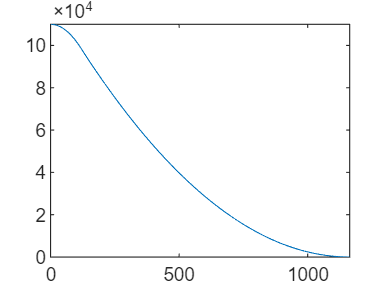

plot(tl, hl);

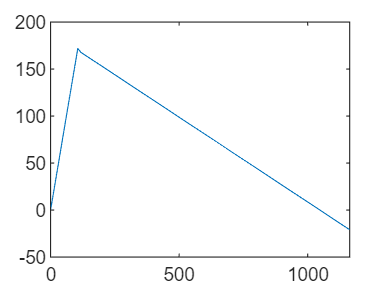

plot(tl, vl);